이상기체 상태방정식은 열역학에서 이상기체의 상태를 설명하는 데 사용되는 기본적인 방정식입니다. 이 방정식은 다음과 같습니다:$PV = nRT$

여기서:

- P: 압력 (Pa)

- V: 부피 (m³)

- n: 몰수 (mol)

- R: 기체 상수 $(8.314 \, \text{J/(mol\cdot K)})$

- T: 온도 (K)

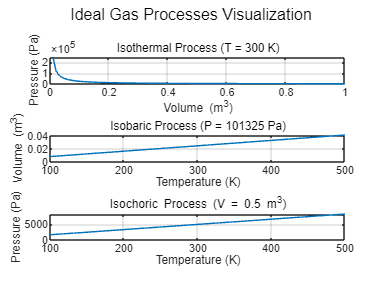

% 상수 정의
R = 8.314; % 기체 상수 (J/(mol·K))
n = 1; % 기체 몰수 (mol)

% 등온 과정
T_isothermal = 300; % 등온 과정 온도 (K)
V_range = linspace(0.01, 1, 100); % 부피 범위 (m³)
P_isothermal = (n * R * T_isothermal) ./ V_range; % 이상기체 상태방정식

% 등압 과정
P_isobaric = 101325; % 등압 과정 압력 (Pa)
T_range = linspace(100, 500, 100); % 온도 범위 (K)
V_isobaric = (n * R * T_range) / P_isobaric; % 이상기체 상태방정식

% 등적 과정
V_isochoric = 0.5; % 등적 과정 부피 (m³)
P_isochoric = (n * R * T_range) / V_isochoric; % 이상기체 상태방정식

% 그래프 그리기
figure;

% 등온 과정
subplot(3, 1, 1);
plot(V_range, P_isothermal);
xlabel('Volume (m^3)');
ylabel('Pressure (Pa)');
title('Isothermal Process (T = 300 K)');
grid on;

% 등압 과정
subplot(3, 1, 2);
plot(T_range, V_isobaric);
xlabel('Temperature (K)');
ylabel('Volume (m^3)');
title('Isobaric Process (P = 101325 Pa)');
grid on;

% 등적 과정
subplot(3, 1, 3);
plot(T_range, P_isochoric);
xlabel('Temperature (K)');
ylabel('Pressure (Pa)');
title('Isochoric Process (V = 0.5 m^3)');
grid on;

sgtitle('Ideal Gas Processes Visualization');

- 특정 기체의 몰수 $n=1 mol$로 고정.

- 온도는 200K에서 500K까지 증가.

- 부피는 0.1 m³에서 1 m³까지 증가.

- 압력은 이상기체 상태방정식 $PV = nRT$에 의해 계산.

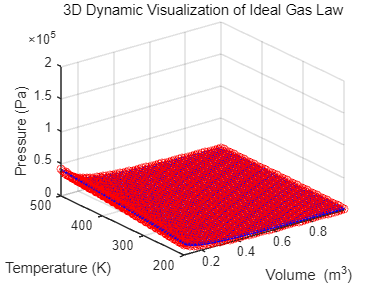

% 상수 정의
R = 8.314; % 기체 상수 (J/(mol·K))
n = 1; % 기체 몰수 (mol)

% 부피와 온도의 범위 설정
V_range = linspace(0.1, 1, 50); % 부피 범위 (m³)
T_range = linspace(200, 500, 50); % 온도 범위 (K)

% 3D 그래프를 위한 격자 생성
[V, T] = meshgrid(V_range, T_range);

% 이상기체 상태방정식에 따른 압력 계산
P = (n * R * T) ./ V;

% 3D 동적 그래프 그리기
figure;
for t = 1:length(T_range)
    % 현재 온도에 따른 압력 계산
    P_dynamic = (n * R * T_range(t)) ./ V_range;
    
    % 3D 그래프 업데이트
    plot3(V_range, T_range(t) * ones(size(V_range)), P_dynamic, 'b-');
    hold on;
    scatter3(V_range, T_range(t) * ones(size(V_range)), P_dynamic, 'ro');
    xlabel('Volume (m^3)');
    ylabel('Temperature (K)');
    zlabel('Pressure (Pa)');
    title('3D Dynamic Visualization of Ideal Gas Law');
    xlim([0.1 1]);
    ylim([200 500]);
    zlim([0 200000]);
    grid on;
    pause(0.1); % 애니메이션 속도 조절
end
hold off;

## 카르노 사이클

**카르노 효율 계산**

카르노 사이클의 효율 $(\eta)$은 다음과 같이 계산됩니다:

$\eta = 1 - \frac{T_C}{T_H}$��

- 
$$T_H = 500 \, \text{K}$$


- 
$$T_C = 300 \, \text{K}$$



$$\eta = 1 - \frac{300}{500} = 1 - 0.6 = 0.4$$


즉, 이 카르노 사이클의 이론적인 최대 효율은 40%입니다. 이는 이 증기 기관이 주어진 온도 범위에서 열을 얼마나 효율적으로 기계적 일로 변환할 수 있는지를 나타냅니다.

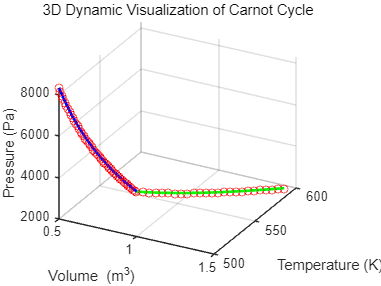

% 상수 정의
R = 8.314; % 기체 상수 (J/(mol·K))
n = 1; % 기체 몰수 (mol)

% 온도 설정
T_hot = 500; % 고온 열원 온도 (K)
T_cold = 300; % 저온 열원 온도 (K)

% 부피 설정
V1 = 0.5; % 초기 부피 (m^3)
V2 = 1.0; % 등온 팽창 후 부피 (m^3)
V3 = 2.0; % 단열 팽창 후 부피 (m^3)
V4 = 1.0; % 등온 압축 후 부피 (m^3)
V5 = 0.5; % 단열 압축 후 부피 (m^3)

% 3D 그래프 그리기
figure;
hold on;
grid on;

% 그래프 라벨 설정
xlabel('Volume (m^3)');
ylabel('Temperature (K)');
zlabel('Pressure (Pa)');
title('3D Dynamic Visualization of Carnot Cycle');
view(3); % 초기 뷰 설정

% 등온 팽창 (T = T_hot)
V_range1 = linspace(V1, V2, 50);
P_isothermal1 = (n * R * T_hot) ./ V_range1;

% 단열 팽창
gamma = 1.4; % 이상 기체의 비열비 (주로 단원자 기체의 경우)
P_adiabatic2 = P_isothermal1(end) * (V2 ./ linspace(V2, V3, 50)).^gamma;
V_range2 = linspace(V2, V3, 50);

% 등온 압축 (T = T_cold)
V_range3 = linspace(V3, V4, 50);
P_isothermal3 = (n * R * T_cold) ./ V_range3;

% 단열 압축
P_adiabatic4 = P_isothermal3(end) * (V4 ./ linspace(V4, V5, 50)).^gamma;
V_range4 = linspace(V4, V5, 50);

% 애니메이션 그리기
for t = 1:50
    % 단계에 따라 그래프 업데이트
    if t <= 50
        plot3(V_range1(1:t), T_hot * ones(1, t), P_isothermal1(1:t), 'b', 'LineWidth', 2);
        scatter3(V_range1(t), T_hot, P_isothermal1(t), 'ro');
    end
    if t > 25 && t <= 75
        idx = t - 25;
        plot3(V_range2(1:idx), T_hot * (V_range2(1:idx) ./ V2).^(gamma-1), P_adiabatic2(1:idx), 'g', 'LineWidth', 2);
        scatter3(V_range2(idx), T_hot * (V_range2(idx) / V2)^(gamma-1), P_adiabatic2(idx), 'ro');
    end
    if t > 50 && t <= 100
        idx = t - 50;
        plot3(V_range3(1:idx), T_cold * ones(1, idx), P_isothermal3(1:idx), 'r', 'LineWidth', 2);
        scatter3(V_range3(idx), T_cold, P_isothermal3(idx), 'ro');
    end
    if t > 75 && t <= 125
        idx = t - 75;
        plot3(V_range4(1:idx), T_cold * (V_range4(1:idx) ./ V4).^(gamma-1), P_adiabatic4(1:idx), 'm', 'LineWidth', 2);
        scatter3(V_range4(idx), T_cold * (V_range4(idx) / V4)^(gamma-1), P_adiabatic4(idx), 'ro');
    end

    % 그래프 회전
    view(3 + t * 0.5, 30); % 동적으로 회전시키기 위한 뷰 설정

    pause(0.1); % 애니메이션 속도 조절
end

hold off;

**아이스크림 녹기 과정에서의 엔트로피 변화**

**가정**:

- 아이스크림의 초기 온도: $-5^\circ \text{C} (268 K)$

- 아이스크림이 완전히 녹은 후의 온도: $0^\circ \text{C}(273 K)$

- 아이스크림의 질량: $100 \, \text{g}$

- 아이스크림의 융해열 (얼음의 융해열):$L_f = 334 \, \text{J/g}$

- 주변 환경의 온도: $25^\circ \text{C} (298 K)$

**엔트로피 변화 계산**:

- **아이스크림 자체의 엔트로피 변화**:

- 아이스크림이 녹는 과정은 두 단계로 나누어 생각할 수 있습니다.

- 고체 아이스크림이 0°C까지 가열되는 단계 (등적 과정)

- 0°C에서 녹는 과정 (등온 과정)

- 먼저, 아이스크림이 0°C까지 가열되는 과정은 거의 등적 과정으로, 이 과정에서 엔트로피 변화는 무시할 수 있을 정도로 작다고 가정합니다.

- 아이스크림이 녹는 동안 발생하는 엔트로피 변화는 다음과 같이 계산됩니다:

$\Delta S_{\text{ice}} = \frac{Q_{\text{melt}}}{T} = \frac{m L_f}{T}$��

- $Q_{\text{melt}}$는 융해 과정에서 흡수된 열이고, T는 절대 온도입니다.

- 
$$m = 100 \, \text{g} = 0.1 \, \text{kg}$$


- 
$$L_f = 334 \, \text{J/g} = 334,000 \, \text{J/kg}$$


- 
$$온도 T = 273 \, \text{K}$$



$$\Delta S_{\text{ice}} = \frac{0.1 \times 334,000}{273} \approx 122.3 \, \text{J/K}$$


- **주변 환경의 엔트로피 변화**:

- 주변 환경이 아이스크림에 열을 공급하여 아이스크림이 녹게 됩니다.

- 주변 환경이 아이스크림에 공급한 열은 아이스크림이 흡수한 것과 동일하지만 부호가 반대입니다.

$\Delta S_{\text{env}} = -\frac{Q_{\text{melt}}}{T_{\text{env}}}$��

- 
$$T_{\text{env}} = 298 \, \text{K}$$



$$\Delta S_{\text{env}} = -\frac{0.1 \times 334,000}{298} \approx -112.1 \, \text{J/K}$$


- **전체 엔트로피 변화**:$\Delta S_{\text{total}} = \Delta S_{\text{ice}} + \Delta S_{\text{env}}\Delta S_{\text{total}} = 122.3 \, \text{J/K} - 112.1 \, \text{J/K} = 10.2 \, \text{J/K}$

**해석**

- 이 예시에서 아이스크림이 녹는 동안 아이스크림 자체는 엔트로피가 증가하고, 주변 환경은 엔트로피가 감소합니다.

- 그러나 전체 시스템(아이스크림 + 주변 환경)의 엔트로피 변화는 양수입니다. 즉, 엔트로피가 증가합니다.

- 이는 **열역학 제2법칙**과 일치합니다. 고립된 시스템(여기서는 아이스크림과 주변 환경)의 엔트로피는 감소하지 않습니다.

- 자연적으로 일어나는 모든 과정에서 전체 엔트로피는 항상 증가하거나 일정하게 유지됩니다.

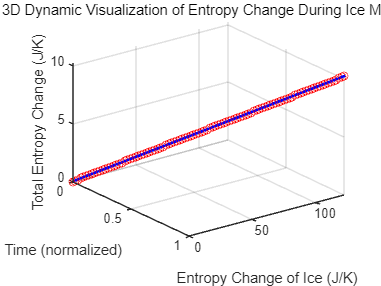

% 상수 정의
m = 0.1; % 아이스크림의 질량 (kg)
Lf = 334000; % 융해열 (J/kg)
T_melt = 273; % 아이스크림의 녹는 온도 (K)
T_env = 298; % 주변 환경의 온도 (K)
Q_melt = m * Lf; % 아이스크림이 녹는 동안 흡수하는 열 (J)

% 시간 설정
time_steps = 100; % 시간 단계 수
time = linspace(0, 1, time_steps); % 시간

% 엔트로피 변화 계산
S_ice = (time * Q_melt) / T_melt; % 아이스크림의 엔트로피 변화 (J/K)
S_env = -(time * Q_melt) / T_env; % 주변 환경의 엔트로피 변화 (J/K)
S_total = S_ice + S_env; % 전체 엔트로피 변화 (J/K)

% 3D 그래프 그리기
figure;
hold on;
grid on;
xlabel('Time (normalized)');
ylabel('Entropy Change of Ice (J/K)');
zlabel('Total Entropy Change (J/K)');
title('3D Dynamic Visualization of Entropy Change During Ice Melting');

% 뷰 초기화
view(3);

% 동적 그래프
for t = 1:time_steps
    % 동적 데이터 그리기
    plot3(time(1:t), S_ice(1:t), S_total(1:t), 'b', 'LineWidth', 2);
    scatter3(time(t), S_ice(t), S_total(t), 'ro');
    
    % 축 제한 설정
    xlim([0 1]);
    ylim([0 max(S_ice)]);
    zlim([min(S_total) max(S_total)]);
    
    % 그래프 회전
    view(3 + t*0.5, 30); % 동적으로 회전시키기 위한 뷰 설정

    pause(0.1); % 애니메이션 속도 조절
end

hold off;

**사례: 랭킨 사이클의 T-S 선도**

**가정**:

- 보일러에서 고온 고압의 증기를 생성합니다.

- 터빈에서 증기가 팽창하면서 일을 합니다.

- 응축기에서 증기를 냉각하여 물로 응축합니다.

- 펌프로 응축된 물을 다시 보일러로 보내어 압축합니다.

**랭킨 사이클의 네 단계**

- **등엔트로피 압축 (펌프 과정)**:

- 냉각된 물을 펌프를 사용하여 보일러로 보내는 과정입니다.

- 이 과정에서는 엔트로피가 일정하게 유지되고, 압력과 온도는 증가하지만 그 폭은 작습니다.

- T-S 선도에서 이 과정은 수직선으로 표시됩니다.

- **등압 가열 (보일러에서 가열)**:

- 물을 보일러에서 가열하여 고압의 증기로 만듭니다.

- 이 과정에서는 압력이 일정하며, 온도와 엔트로피가 증가합니다.

- T-S 선도에서 이 과정은 오른쪽으로 기울어진 곡선으로 표시됩니다.

- **등엔트로피 팽창 (터빈에서 팽창)**:

- 증기는 터빈을 통과하면서 팽창하고 일을 합니다.

- 이 과정에서는 엔트로피가 일정하게 유지되고, 압력과 온도가 감소합니다.

- T-S 선도에서 이 과정은 수직선으로 표시됩니다.

- **등압 냉각 (응축기에서 응축)**:

- 터빈을 통과한 후의 증기는 응축기에서 냉각되어 물로 응축됩니다.

- 이 과정에서는 압력이 일정하며, 온도와 엔트로피가 감소합니다.

- T-S 선도에서 이 과정은 왼쪽으로 기울어진 곡선으로 표시됩니다.

**구체적인 수치 예시**

- 보일러 압력: $3 \, \text{MPa}$(고압)

- 응축기 압력: $0.01 \, \text{MPa}$ (저압)

- 보일러에서의 증기 온도: $350^\circ \text{C} (623 K)$

- 응축기에서의 응축 온도: $45^\circ \text{C} (318 K)$

**단계별로 계산된 엔트로피와 온도**

- **펌프 과정** $(1 \rightarrow 2)$:

- 물의 초기 상태: 포화액체 상태, 압력 $0.01 \, \text{MPa}$, 온도 $45^\circ \text{C}$

- 엔트로피: $S_1 = S_2$ (등엔트로피 과정)

- 온도: 약간 상승하지만 큰 변화는 없음

- **보일러 가열** $(2 \rightarrow 3):$

- 보일러에서의 상태: 압력$3 \, \text{MPa}$

- 증기 상태: 과열 증기, 온도 $350^\circ \text{C}$

- 엔트로피 변화: $S_3 - S_2$ (엔트로피 증가)

- **터빈 팽창** $(3 \rightarrow 4):$

- 터빈 출구 상태: 압력 $0.01 \, \text{MPa}$

- 온도: 응축기 입구의 포화 증기 온도

- 엔트로피: $S_4 = S_3$ (등엔트로피 과정)

- **응축기 냉각** $(4 \rightarrow 1):$

- 응축기 출구 상태: 포화액체 상태

- 압력: $0.01 \, \text{MPa}$

- 엔트로피 감소: $S_4 - S_1$�

**T-S 선도에서의 해석**

- **T-S 선도 해석**:

- 수직선 $(1 \rightarrow 2$와$3 \rightarrow 4)$은 각각 펌프와 터빈에서의 등엔트로피 과정(압축과 팽창)을 나타냅니다.

- 오른쪽으로 기울어진 곡선 $(2 \rightarrow 3)$은 보일러에서의 가열 과정으로, 엔트로피와 온도가 증가합니다.

- 왼쪽으로 기울어진 곡선 $(4 \rightarrow 1)$은 응축기에서의 냉각 과정으로, 엔트로피와 온도가 감소합니다.

- **사이클의 면적**:

- T-S 선도에서 랭킨 사이클을 이루는 면적은 순일(터빈에서 생성되는 일 - 펌프에 필요한 일)을 나타냅니다.

- 이 면적이 클수록 사이클의 효율이 높습니다.

- **열 전달**:

- 보일러에서 흡수되는 열량과 응축기에서 방출되는 열량을 엔트로피 변화와 온도의 곱을 통해 시각적으로 이해할 수 있습니다.

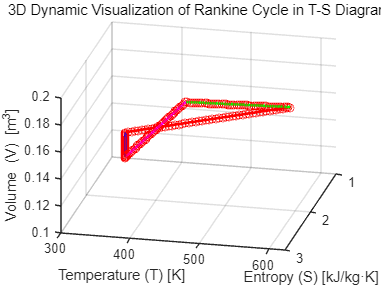

% 상수 정의
R = 8.314; % 기체 상수 (J/(mol·K)), 여기서는 이상적인 경우를 고려
n = 1; % 물질의 몰수 (mol)

% 랭킨 사이클 상태 정의
% 가정된 상태 수치 (온도 T, 엔트로피 S)
T1 = 318; % K, 응축기 출구 온도 (1 -> 포화액체 상태)
T2 = 320; % K, 펌프 출구 온도 (2)
T3 = 623; % K, 보일러 출구 온도 (3 -> 과열 증기 상태)
T4 = 450; % K, 터빈 출구 온도 (4 -> 포화증기 상태)

S1 = 1.0; % kJ/kg·K, 상태 1의 엔트로피 (임의 수치)
S2 = 1.05; % kJ/kg·K, 상태 2의 엔트로피 (엔트로피 약간 증가)
S3 = 2.8; % kJ/kg·K, 상태 3의 엔트로피 (보일러에서 증가)
S4 = 2.2; % kJ/kg·K, 상태 4의 엔트로피 (터빈 팽창 후)

% 랭킨 사이클 각 단계
% 1 -> 2: 펌프 (등엔트로피 압축)
% 2 -> 3: 보일러 가열 (등압 가열)
% 3 -> 4: 터빈 팽창 (등엔트로피 팽창)
% 4 -> 1: 응축기 냉각 (등압 냉각)

% 3D 그래프 그리기
figure;
hold on;
grid on;

% 그래프 라벨 설정
xlabel('Entropy (S) [kJ/kg·K]');
ylabel('Temperature (T) [K]');
zlabel('Volume (V) [m^3]');
title('3D Dynamic Visualization of Rankine Cycle in T-S Diagram');

% 뷰 초기화
view(3);

% 엔트로피와 부피의 상태 변화 시뮬레이션
time_steps = 50; % 시간 단계 수
total_steps = 4 * time_steps; % 총 단계 수
for t = 1:total_steps
    % 등엔트로피 압축 (1 -> 2)
    S12 = linspace(S1, S2, time_steps);
    T12 = linspace(T1, T2, time_steps);
    V12 = linspace(0.1, 0.12, time_steps); % 임의의 부피 변화
    
    % 등압 가열 (2 -> 3)
    S23 = linspace(S2, S3, time_steps);
    T23 = linspace(T2, T3, time_steps);
    V23 = linspace(0.12, 0.2, time_steps); % 임의의 부피 변화
    
    % 등엔트로피 팽창 (3 -> 4)
    S34 = linspace(S3, S4, time_steps);
    T34 = linspace(T3, T4, time_steps);
    V34 = linspace(0.2, 0.18, time_steps); % 임의의 부피 변화
    
    % 등압 냉각 (4 -> 1)
    S41 = linspace(S4, S1, time_steps);
    T41 = linspace(T4, T1, time_steps);
    V41 = linspace(0.18, 0.1, time_steps); % 임의의 부피 변화
    
    % 동적 그래프 그리기
    if t <= time_steps
        plot3(S12(1:t), T12(1:t), V12(1:t), 'b', 'LineWidth', 2);
        scatter3(S12(t), T12(t), V12(t), 'ro');
    elseif t <= 2 * time_steps
        idx = t - time_steps;
        plot3(S23(1:idx), T23(1:idx), V23(1:idx), 'r', 'LineWidth', 2);
        scatter3(S23(idx), T23(idx), V23(idx), 'ro');
    elseif t <= 3 * time_steps
        idx = t - 2 * time_steps;
        plot3(S34(1:idx), T34(1:idx), V34(1:idx), 'g', 'LineWidth', 2);
        scatter3(S34(idx), T34(idx), V34(idx), 'ro');
    elseif t <= 4 * time_steps
        idx = t - 3 * time_steps;
        plot3(S41(1:idx), T41(1:idx), V41(1:idx), 'm', 'LineWidth', 2);
        scatter3(S41(idx), T41(idx), V41(idx), 'ro');
    end

    % 뷰 회전
    view(3 + t * 0.5, 30); % 동적으로 회전시키기 위한 뷰 설정

    pause(0.1); % 애니메이션 속도 조절
end

hold off;